# **Number Operator and the potential family**$V\approx q^{\alpha }$

In this section we want to explore the use of the number operator and study its effect on the calculation of the Hamiltonian spectrum, starting with the quartic oscillator to later adress the harmonic oscillator problem.

Let's start with the creation operator $a^{\dagger }$ and its conjugate complex, the destruction operator $a$: we can write a representation for the position  $\hat{q\;}$ and the momentum  $\hat{\;p}$  according to $a,a^{\dagger }$:

$q=\frac{1}{\sqrt2}(a+a^\dagger)   $  and $p=-\frac{i}{\sqrt{2}}\left(a-a^{\dagger } \right)$

We remember that $a|n\rangle =\sqrt{n}|n-1\rangle \;\textrm{and}\;a^{\dagger } |n\rangle =\sqrt{n+1}|n+1\rangle$

and that the solution to the eigenvalues for the Hamiltonian of the harmonic oscillator is

$H=\frac{p^2 }{2}+\frac{q^2 }{2}\;$ è $H|n\rangle =\left({\textrm{aa}}^{\dagger } +\frac{1}{2}\right)|n\rangle$

Eigenvectors $|n\rangle \;$have as functional form : the hermite polynomials $\Psi_n \left(x\right)\;\textrm{with}\;n=1,\ldotp \ldotp ,N$.

We also recall  that the application of the position operator on an eigenstate of the harmonic oscillator is given by the recurrence rule:$\;x\;\Psi_n \left(x\right)=\sqrt{\frac{n}{2}}\Psi_{n-1} \left(x\right)+\sqrt{\frac{n+1}{2}}\;\Psi_{n+1} \left(x\right)$

So if we use the position operator q on an eigenstate of the position base $|x\rangle_N$ we have


$$q\vert x\rangle_N=x\vert x \rangle_N -\frac{1}{2}\Psi_{N+1}(x)\sqrt{N+1} \vert N \rangle + \frac{1}{2}\Psi_{N}(x)\sqrt{N+1} \vert N+1 \rangle$$


To transpose this problem onto a discrete lattice, we need to truncate the occupancy number space $N\;$, representing the number operator on a finite base, numbered by $n=0,1,2,\ldotp \ldotp \ldotp ,N\;\ldotp$  We are no longer able to us$|\;N+1\;\rangle$, because it is not available, therefore the representation of the action of on a state $|x\rangle_N$ reduces to


$$q\vert x\rangle_N=x\vert x \rangle_N -\frac{1}{2}\Psi_{N+1}(x)\sqrt{N+1} \vert N \rangle $$


If we choose to reset the last term to zero: $\Psi_{N+1} \left(x_j^{\left(N+1\right)} \right)=0$

we obtain an eigenvalues equation for $q$ for which eigenvalues are just the positions $\left(x_j^{\left(N+1\right)} \right)$.


$$q\vert x_j ^{(N+1)} \rangle = x_j ^{(N+1)} \vert x_j ^{(N+1)}\rangle\;\;\;with\;\;\;j=0,1,...,N
$$


We can assert that the spectrum of the operator q in the truncated space of the occupation number is given by the zeros of the Hermite polynomial $\Psi_{N+1} \left(x\right)$, which are nothing more than the positions $x_j$ of the discrete graph obtained from the diagonalization of $\hat{q}$.

Truncating the occupation number to finite N is equivalent to not use the series of hermite polynomials of higher order to N:$N+1,\ldotp \ldotp \ldotp ,\infty$ ; in an ideal world the occupation number would not be truncated and the eigenvalues of q would be all the x's on the real axis.

The volume (L) in which we represent the problem is automatically determined by $L=\textrm{Na}$. 

%we choose to cut the representation to an occupation number N=2e3
N=1e3;
%defining a and a' on the truncate space
a = diag(sqrt(1:N-1),1);
%defining q on the truncate space
q = (a+a')/sqrt(2);
%defining N on the truncate space 
H0 = diag((0:N-1)+1/2); 

$H_0 =\textrm{diag}\left(N+\frac{1}{2}\right)$is the Hamiltonian of the harmonic oscillator in base of the number operator; here the Hamiltonian is diagonal and its as eigenvalues are those just seen; Let's start by representing the Hamiltonian of the quartic oscillator $H_{\textrm{quartic}} =\frac{p^2 }{2}+\frac{q^4 }{24}$. We want to get this Hamiltonian from the number operator e and to do so we write $H_{\textrm{quartic}\;} =H_0 -\frac{q^2 }{2}+\frac{q^4 }{24}$ ;  We need to use the matrix expression of the operator and derive its eigenvalues

x = eig(q);

Now we are able to represent the quartic Hamiltonian on the basis of the number operator; the last consideration to do before solving the spectrum of the quartic oscillator is the one concerning the scale size.

We estimate the dependence of the operators kinetic energy T and potential V from the lattice step, which in turn is uniquely determined from the truncated occupation number N and to do so we take into account the approach already used; the potential V is written as $V\approx q^4$; it is clear that the trend of the operator $q$ is directly proportional to the lattice spacing $a$ in the position space $x$, i.e. in the "direct" grid $V\approx q^4 \approx a^4 \;$ ( the potential written now in the base of the number operator works as long as the lattice spacing of the direct lattice is equal to 1, this is not our case; the lattice spacing $a$is determined by the maximum number of occupancy).

The kinetic energy this has a dependence of the type $T =\frac{{p }^2 }{2}=\frac{{k }^2 }{2}=\frac{1}{2}\left(\frac{2\pi }{N\cdot a\;}n\right){\;}^2 \;|_{n_{\;} =\;\frac{N}{2}\;} =\frac{\pi^2 }{a^2 }$

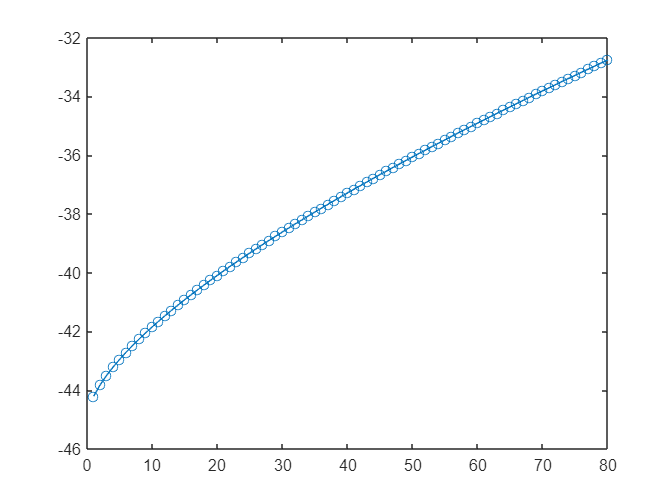

plot(x(1:80),'o-')

Here we can see a plot of the grid for the first 80 positions; we note that the direct lattice has a lattice spacing that decreases as we move away from the origin because the zeros of the hermite polynomials are not equally distributed in the lattice. The area near the origin 0 and the extreme N is sampled less densely.

There is a theorem wich can help us to understand how zeros of Hemrite polinomials distibute over the real axes for increasing occupation numbers.

**Theorem**: Let x1 < ... < xn be the zeros of  $H_n$, and let $\textrm{y1}<\ldotp \ldotp \ldotp <\textrm{yn}+1$  be the zeros of $H_{n+1}$ then $a<\textrm{y1}<\textrm{x1}<\textrm{y2}<\textrm{x2}<\ldotp \ldotp \ldotp \textrm{yn}<\textrm{xn}<\textrm{yn}+1<b$, that is, an "interlacing" property between the zeros of Hermite polynomials holds.

We define now for correctness of notation the inverse of the lattice spacing, with which we correct the operators $T,\;V$; the correction to be made is to multiply the operators by the scale magnitude $s=f\left(a\right)\;\textrm{where}\;a\;\textrm{is}\;\textrm{he}\;\textrm{lattice}\;\textrm{spacing}$, to obtain a representation of the operator scaled with the discrete latex.

The potential reaches the right scale size when multiplied by its scale factor: $V={\frac{1}{24}q^4 } \to V=\frac{1}{24}{\left(\frac{q}{w}\right)}^4$ 

The same is true for the kinetic energy, for which we get $T=\frac{1}{2}L\to T=\frac{1\;}{2}L\frac{1}{a^2 }=\frac{1}{2}{\textrm{Lw}}^2$

Now we wonder about the latex spacing $a$ (or the "occupation volume" $w$) for which we have the best representation of the problem from a numerical point of view. We want to make sure that the condition of conservation of energy is satisfied, so we impose that the maximum kinetic energy and the maximum potential energy are equal (it is equivalent to place equal the energies in the points where T cancels, maximum of V, and where V cancels, maximum of T).

The condition must be imposed by considering the correct scale size


$$T_{\max \;} w^2 =\frac{1}{2}{\max \left(w\cdot \;p\right)}^{2\;} \;=\;\frac{1}{24}{\max \left(\frac{x}{w}\right)}^4 ={\frac{1}{w^4 }V_{\max } }$$


and by knowing $\max \left(p\right)\simeq \;\max \left(x\right)$ (is true unless a factor $\pi$), we obtain $w={\left(\frac{V_{\max } }{T_{\max } }\right)}^{\frac{1}{6}} ={\left(\frac{{\max \left(x\right)}^2 }{12}\right)}^{\frac{1}{6}}$

inverse_a = (max(x)^2/12)^(1/6); %inva = w = iverse of optimal lattice spacing 

We finally write the Hamiltonian in which we insert the correct scaling dimensions and find its eigenvalues using the eig algorithm.

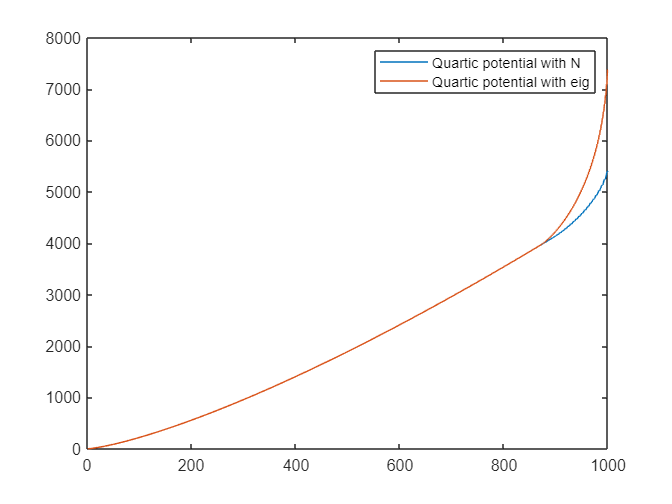

H_quartic = inverse_a^2*(H0-q^2/2)+(q/inverse_a)^4/24;
e = eig(H_quartic);
%[V,D] = eig(H_quartic);
figure
plot(e)
hold on
eH = Vquartic_eig(N);
plot(eH(:,1))
legend('Quartic potential with N ','Quartic potential with eig')

We note that the spectra calculated with the two methods are exactly superimposed for more than 80% of the eigenfunctions;

It is clear that using this procedure to obtain the spectrum of the quartic oscillator is more performant than the diagonalization of a full H matrix, obtained for example using the order form of the Laplacian. This is because, despite eig is used twice the matrices to be diagonalized are: a tridiagonal matrix with the main diagonal consisting only of zeros, and $H_0 -\frac{q^2 }{2}+\frac{q^4 }{24}$ a matrix written as the sum of a diagonal matrix, $H_0$, and $q^2 \;e\;q^4$(both diagonalizable matrices); this ensures a lower computational cost than that associated with diagonalizing a generic square matrix.

Last but not least we have to adress the inherent accuracy of this method. The spectrum of the operator $H_0$ is an exact spectrum by definition; the approximation we are making concerns the truncation of the occupation number and nothing else. The operators involved, in particular T, by construction do not depend on the number of points considered in the lattice. The hermite polynomials computed with qharmoscpsi are exact in precision number.

We repeat the exercise for the harmonic oscillator, but first realize that we can extend the problem to an entire family of potentials of the type $V\approx {\textrm{cost}\cdot q}^{\alpha }$, in the most general case then $a=\frac{1}{w}={\left(\frac{T_{\max } }{V_{\max } }\right)}^{\frac{1}{\alpha +2}}$; we can evaluate (with qharmoscpsi for example) the exact polynomials and check the accuracy of the representation; in the latter the Hamiltonian $H_0 \;$ is diagonal and the only diagonalization needed by eig is that of the operator $q$. 

Before turning to the harmonic oscillator we plot the eigenfunctions of the Hamiltonian problem Number of the harmonic oscillator on the grid of positions obtained as zeros of the N+1 hermite polynomial.

# Harmonic oscillator within the base of the occupation number N.

We use the eig algorithm to obtain eigenvalues and eigenvectors of the harmonic oscillator Hamiltonian $H=\frac{p^2 }{2}+\frac{q^2 }{2}$.

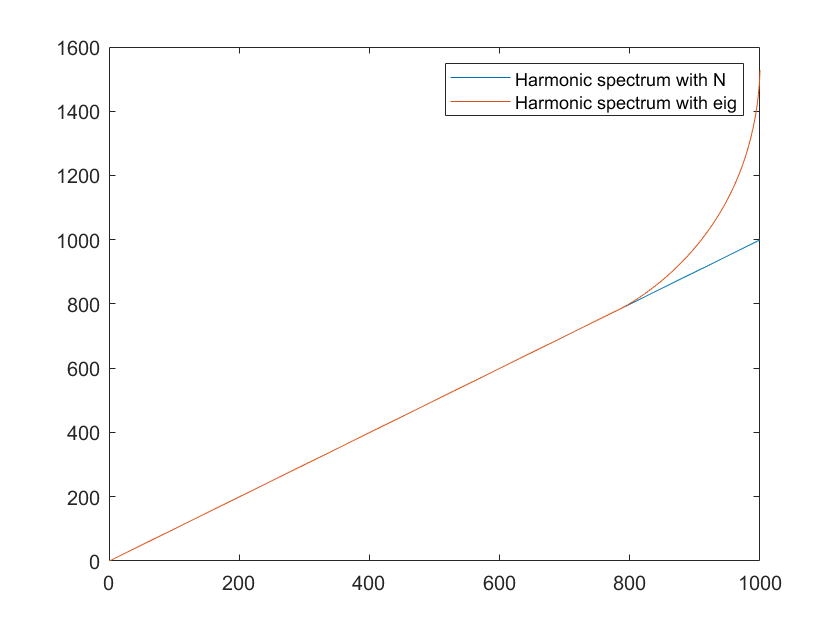

%defining grid by using Number operators eig equation
[Psi,E] = eig(H0);
%We have the eigenvalues and eigenvectors of the Harmonic Oscillator on the
%basis of the occupation number.
E=diag(E);
figure
plot(E)
hold on
%now we plot the spectra of the harmoni oscilator using Hamiltonian1D, the
%classic PBC Fourier transform method
maxT=(pi^2/2);
%maxT,maxV
V = @(x)x.^2/2;
maxV=V(N/2);
%best lattice spacing for conserving energy
optimaldx=(maxT/maxV)^(1/4);
[H,z,Htri] = hamiltonian1D(N,optimaldx,V,'PBC');
F=eig(H);
plot(F)
legend('Harmonic spectrum with N','Harmonic spectrum with eig')

Spectra with the two methods allow us to estimate how reliable are the eigenstates obtained by diagonalizing H  as a multidiagonal matrix of order p-$\infty$ and comparing their accuracy with the exact ones of the number representation. Again, the spectrum obtained with hamiltonian1D is perfectly superimposed on that obtained with the number representation up to very large values of the occupation number.